# Série 5

## Ex1

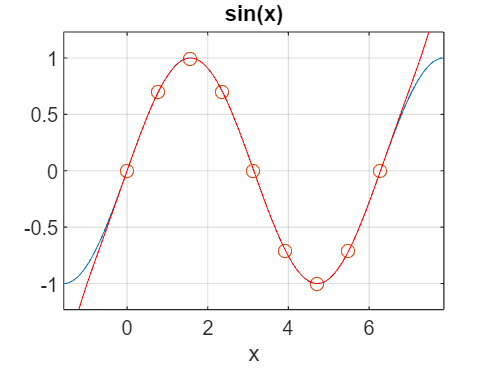

clear;clc;close;

f = @(x) sin(x);
% Point d'interpolation
x = linspace(0, 2*pi, 9);
y = f(x);

% Coefficients
a = polyfit(x, y, 8);

% Dessin des fonctions
ezplot(f, [-pi/2, 5*pi/2]);
grid on;
hold on;

% evaluation du polyonme en 1000 points
xx = linspace(-pi/2, 5*pi/2, 1e3);
p = polyval(a, xx);

plot(x, y, 'o', xx, p, 'r');

## Ex2

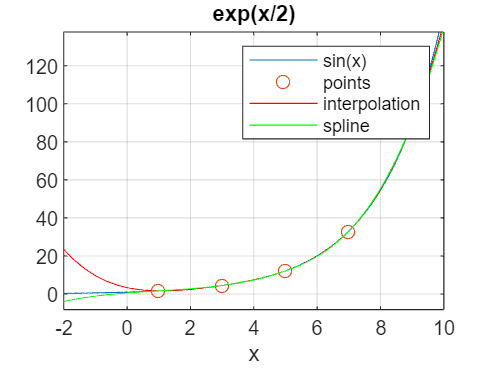

clear;clc;close;

f = @(x) exp(x/2);
% pts interpolation
x = linspace(1, 9, 5);
y = f(x);
% coeff
a = polyfit(x, y, 4);

% evaluation polynome
xx =  linspace(-2, 10, 1e3);
p = polyval(a, xx);

% dessin
ezplot(f, [-2, 10]); grid on; hold on;
plot(x, y, 'o', xx, p, 'r');

% Spline
p2 = spline(x, y, xx);
plot(xx, p2, 'g');
legend('sin(x)', 'points', 'interpolation', 'spline');
hold off;

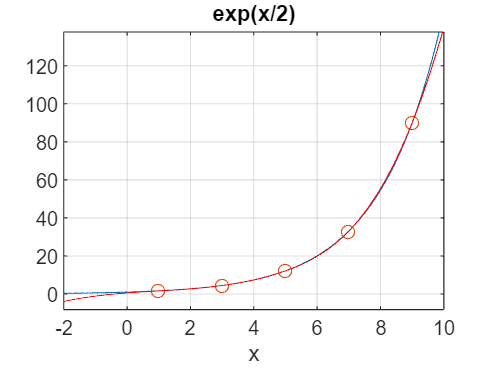

ezplot(f, [-2, 10]); grid on; hold on;
plot(x, y, 'o', xx, p2, 'r');

## Ex3

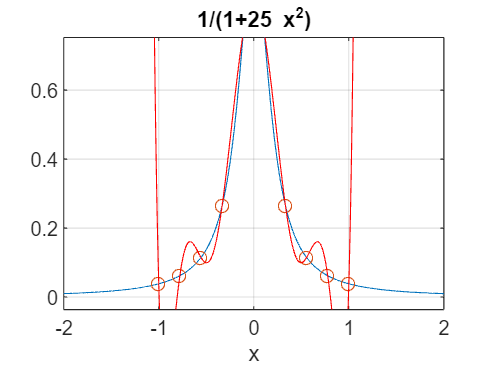

clear;clc;close;

f = @(x) 1./(1+25*x.^2);

x = linspace(-1, 1, 10);
y = f(x);

a = polyfit(x, y, 9);

xx = linspace(-2, 2, 1e3);
p = polyval(a, xx);

ezplot(f, [-2, 2]); hold on; grid on;
plot(x, y, 'o', xx, p, 'r');

## Ex4

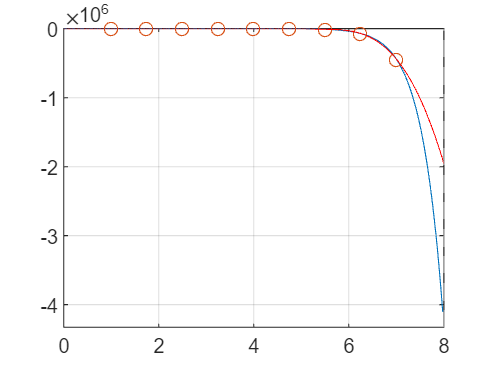

clear;clc;close;

f = @(x) exp(2*x).*cos(log(x));

% 9 points semble être un bon nombre
count = 9;

x = linspace(1, 7, count);
y = f(x);

xx = linspace(0, 8, 1e3);

p = spline(x, y, xx);

fplot(f, [0, 8]);
hold on; grid on;
plot(x, y, 'o', xx, p, 'r');

## Ex5

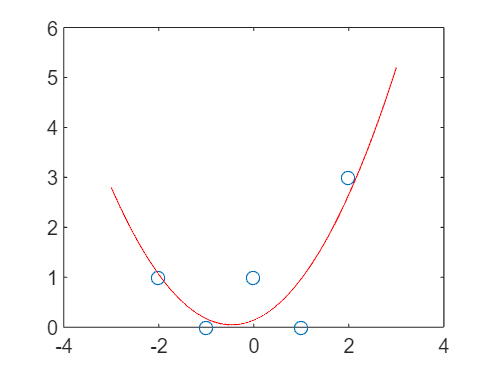

clear;clc;close;

x = -2:2;
y = [1 0 1 0 3];

xx = linspace(-3, 3, 1e3);

% Interpolation avec un polynome de degré 2:
a = polyfit(x, y, 2);
p = polyval(a, xx);
plot(x, y, 'o', xx, p, 'r');

% somme des carrés des résidus :
err_2 = sum((y - polyval(a, x)).^2)

err_2 = 1.8286

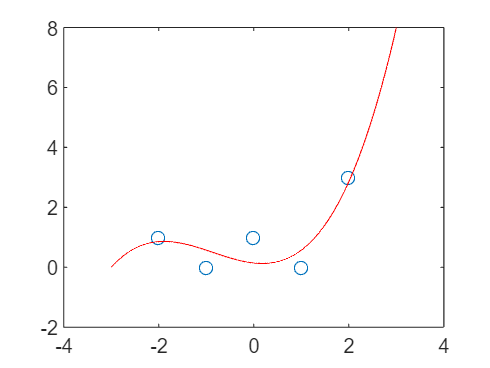



% Interpolation avec un polynome de degré 3:
a = polyfit(x, y, 3);
p = polyval(a, xx);
plot(x, y, 'o', xx, p, 'r');

% somme des carrés des résidus :
err_3 = sum((y - polyval(a, x)).^2)

err_3 = 1.4286

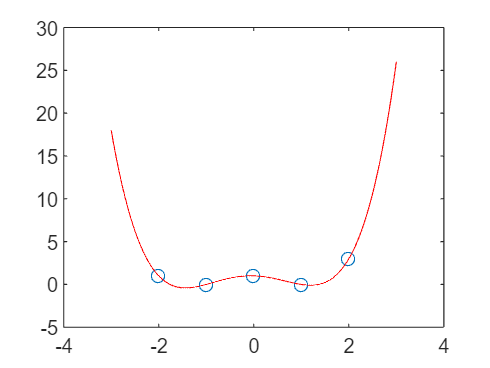



% Interpolation avec un polynome de degré 4:
a = polyfit(x, y, 4);
p = polyval(a, xx);
plot(x, y, 'o', xx, p, 'r');

% somme des carrés des résidus :
err_4 = sum((y - polyval(a, x)).^2)

err_4 = 1.4421e-30

## Ex6


x = 0:3;
y = [1 0 1 0];




